s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



Gp=-30/(s^2+3*s+2)

Gp =
 
       -30
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.




zpk(Gp)

ans =
 
      -30
  -----------
  (s+2) (s+1)
 
Continuous-time zero/pole/gain model.




Gs=1

Gs = 1

Gr=1

Gr = 1

Ga=0.006

Ga = 0.0060

Gf=1

Gf = 1

kc=61.2*-1

kc = -61.2000


wc=1.27

wc = 1.2700

Tp0=1.1

Tp0 = 1.1000

Sp0=1.45

Sp0 = 1.4500

Kd=1

Kd = 1



PI=1+s/(0.508)

PI =
 
  s + 0.508
  ---------
    0.508
 
Continuous-time transfer function.



Ri=(1+s/(4.41*1.27*10^-2))/(1+s/(1.27*10^-2))

Ri =
 
  0.0127 s + 0.0007113
  ---------------------
  0.05601 s + 0.0007113
 
Continuous-time transfer function.




Gc=kc/s*PI*Ri

Gc =
 
  -0.7772 s^2 - 0.4384 s - 0.02211
  --------------------------------
     0.02845 s^2 + 0.0003613 s
 
Continuous-time transfer function.



L=kc/s*Gf*Gs*Ga*Gp*PI*Ri

L =
 
            0.1399 s^2 + 0.07891 s + 0.00398
  -----------------------------------------------------
  0.02845 s^4 + 0.08572 s^3 + 0.05799 s^2 + 0.0007227 s
 
Continuous-time transfer function.



% zpk(L)
% Gc=kc/s*PI*Rd*Rd

% zpk(L)
omega=logspace(-20,20,6000)

omega = 	1.0e+20 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


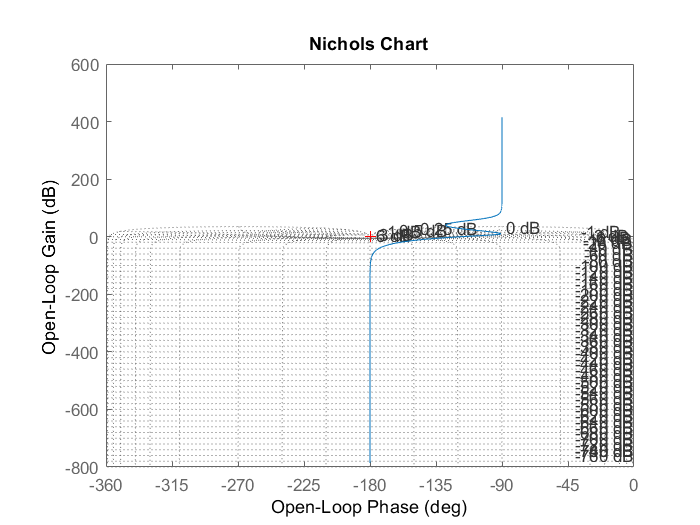

Attempt to execute SCRIPT myngridst as a function:
C:\Users\EREN\Downloads\myngridst.m

Error in NicholsEren (line 5)
myngridst(Tp0,Sp0)


% bode(L)
% nyquist(L)

NicholsEren(L, omega, Sp0, Tp0);


% controlSystemDesigner(Gp,Gc,1,1)
